% 30 noeuds
a11 = -0.19003; a12 = 4.4802; a14 = 0.0014673;
a21 = 0.0085526; a22 = -0.45988; a24 = -0.0056095;
a34 = -15.433; b11 = -0.1855; b12 = -0.57149;
b21 = 0.043308; b22 = -0.055543;

a11 = -0.19003; a12 = 4.4802; a14 = 0.0014673;
a21 = 0.0085526; a22 = -0.45988; a24 = -0.0056095;
a34 = -15.433; b11 = -0.1855; b12 = -0.57149;
b21 = 0.043308; b22 = -0.055543;

A = [ a11 a12 0 a14; 
      a21 a22 0 a24;
      1   0   0 a34;
      0   1   0   0];
B = [ b11 b12;
      b21 b22;
      0    0 ;
      0    0 ];
C = [0 0 1 0;
     0 0 0 1];
D = [0 0;
     0 0];
syst = ss(A,B,C,D);

%% Commandability et observability
Qc = ctrb(A,B);
Qo = obsv(A,C);

rc = rank(Qc)

rc = 4

ro = rank(Qo)

ro = 4

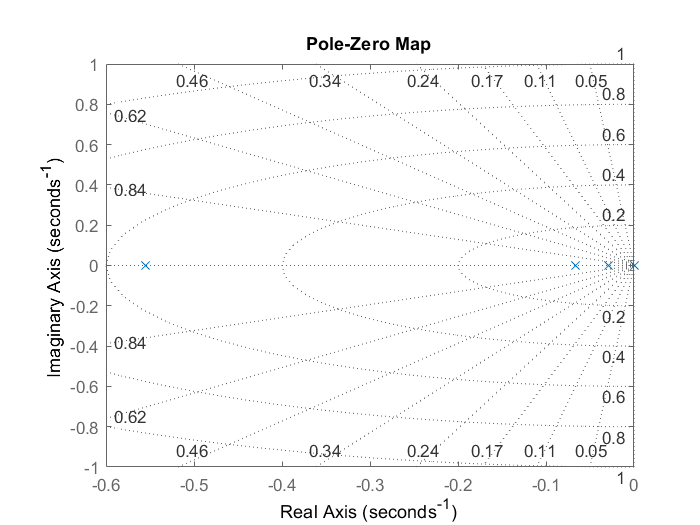


pzmap(syst); grid on

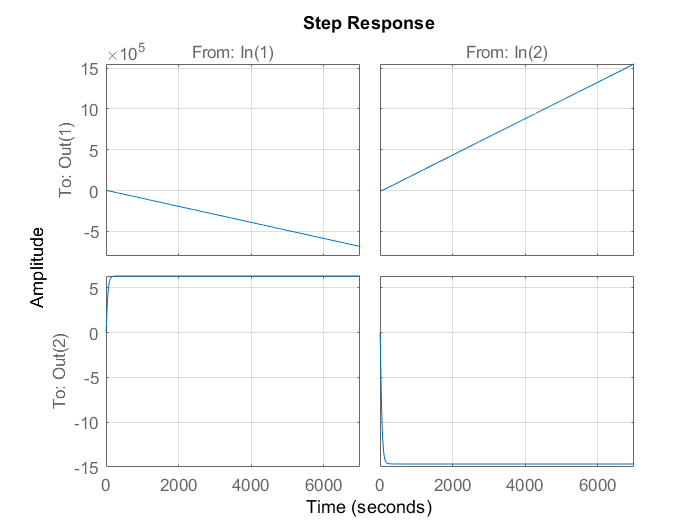


% Step response 
stepplot(syst); grid on ;

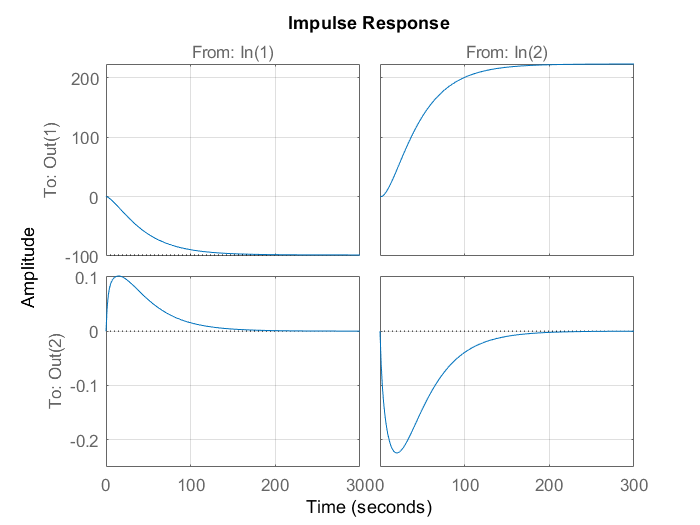


 impulse(syst); grid on;

 
 lamda1=-3/100;
lamda2=lamda1*100;
lamda3=-3/80;
lamda4=lamda3*100;

Nlamda2=-inv(lamda2*eye(4,4)-A)*B;
Nlamda1=-inv(lamda1*eye(4,4)-A)*B;
Nlamda3=-inv(lamda3*eye(4,4)-A)*B;
Nlamda4=-inv(lamda4*eye(4,4)-A)*B;


v1_tilde = [0;
            1];
v2_tilde = [0;
            1];
v3_tilde = [1;
            0];
v4_tilde = [1;
            0];

Nlamda3_tilde = Nlamda3(3:4,:);
Nlamda1_tilde = Nlamda1(3:4,:);
Nlamda2_tilde = Nlamda2(3:4,:);
Nlamda4_tilde = Nlamda4(3:4,:);

z1 = inv(Nlamda1_tilde'*Nlamda1_tilde)*transpose(Nlamda1_tilde)*v1_tilde;
z2 = inv(Nlamda2_tilde'*Nlamda2_tilde)*transpose(Nlamda2_tilde)*v2_tilde;
z3 = inv(Nlamda3_tilde'*Nlamda3_tilde)*transpose(Nlamda3_tilde)*v3_tilde;
z4 = inv(Nlamda4_tilde'*Nlamda4_tilde)*transpose(Nlamda4_tilde)*v4_tilde;

v1 = Nlamda1*z1;
v2 = Nlamda2*z2;
v3 = Nlamda3*z3;
v4 = Nlamda4*z4;

V = [v1 v2 v3 v4]

V =    15.4343   15.4330   -0.0375   -3.7500
   -0.0300   -3.0000    0.0000    0.0000
   -0.0000    0.0000    1.0000    1.0000
    1.0001    1.0000   -0.0000   -0.0000



Z = [z1 z2 z3 z4];

K = Z*inv(V)

K =    -5.5609   59.2569   -0.2228   93.9932
   -4.4899   -0.0688   -0.1737   71.7690





UB=inv(V)*B;
UB_inv = inv(UB'*UB);
UB_inter = UB_inv*UB';
star1 =  -lamda1*2/V(4,1);%(1/5.48)*1/(3*V(4,1));
star2 = 0; %-lamda2*1*0/V(4,2);
star3 = -lamda3*2/V(3,3); % (1/13.19)*1/V(3,3);
star4 = 0; %-lamda4*1*0.5/V(3,4);
h1 = UB_inter(1,3)*star3 + UB_inter(1,4)*star4; h2 = UB_inter(1,1)*star1 + UB_inter(1,2)*star2;
h3 = UB_inter(2,3)*star3 + UB_inter(2,4)*star4; h4 = UB_inter(2,1)*star1 + UB_inter(2,2)*star2;
H=[h1 h2;h3 h4]

H =    -0.2206    1.4525
   -0.1720   -0.4715


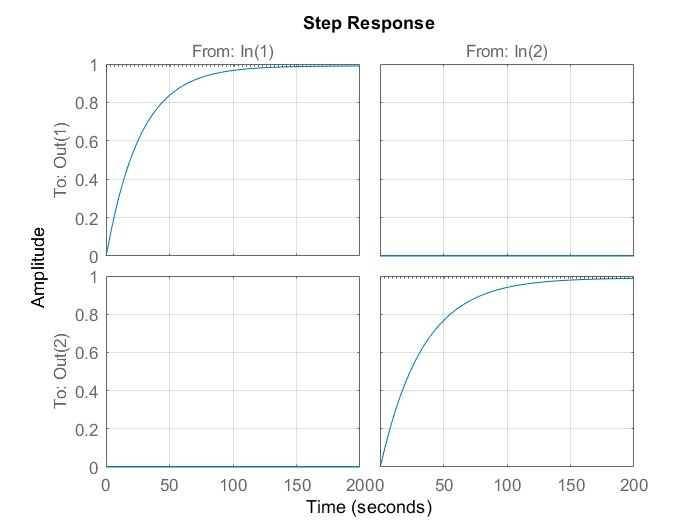

Acl=(A-B*K);
Bcl= B*H;
sys=ss(Acl,Bcl,C,0);
stepplot(sys); grid on;


Omega_inv = [A        B;
             C   zeros(2,2)];
Omega = inv(Omega_inv);
H = Omega(5:6,5:6) + K*Omega(1:4,5:6)

H =    -0.2228    1.4673
   -0.1737   -0.4763


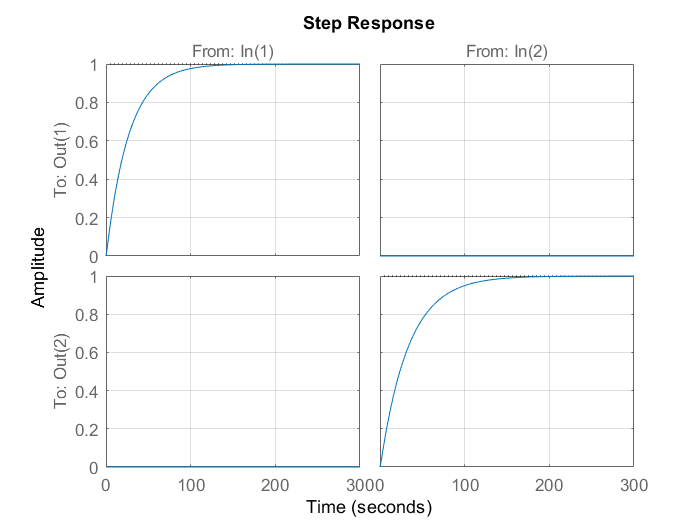

syst_static_decoupled = ss(Abf,B*H,C,0);
stepplot(syst_static_decoupled); grid on;


Poles = [lamda1; lamda2;lamda3; lamda4]

Poles =    -0.0300
   -3.0000
   -0.0375
   -3.7500


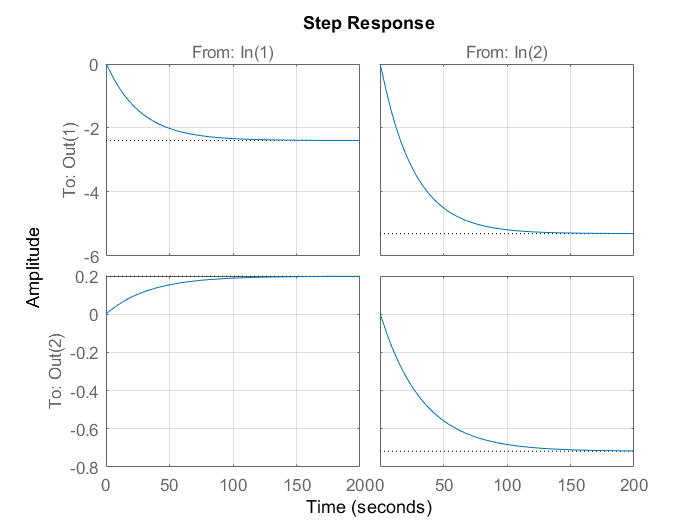

K = place(A,B,Poles);
Abf= A-B*K;
syst_mode_placement = ss(Abf,B,C,0);
stepplot(syst_mode_placement); grid on;

Abf = A - B*K;
[V, D] = eig(Abf);
sensibilite = cond(V);
disp('Sensitivité du placement de mode :'); disp(sensibilite);

Sensitivité du placement de mode :
   29.0196




[V, D] = eig(Acl);
sensibilite = cond(V);
disp('Sensitivité du placement de structure propre :'); disp(sensibilite);

Sensitivité du placement de structure propre :
   39.7889




B2 = B(:,2);
B2 = [0*B(:,1) B2]

B2 =          0   -0.5715
         0   -0.0555
         0         0
         0         0


Poles = [lamda1; lamda2;lamda3; lamda4];
K2 = place(A,B2,Poles)

K2 =          0         0         0         0
  -21.3529  108.6613    0.0538  -43.8474


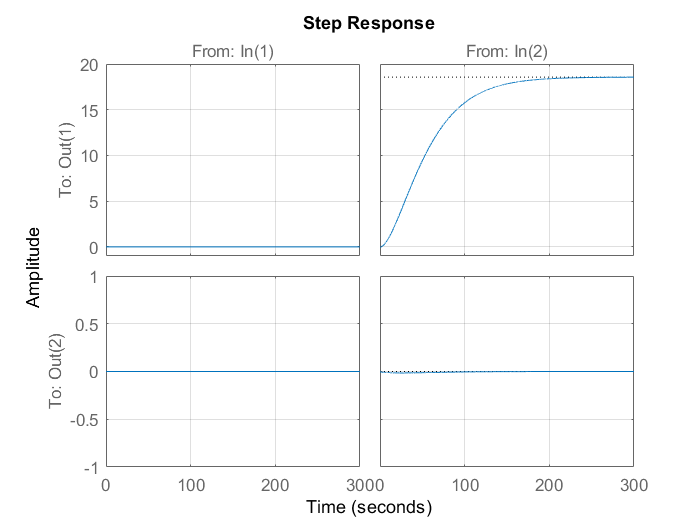

stepplot(ss(A-B2*K2,B2,C,0)); grid on;


[V, D] = eig(A-B2*K2);
sensibilite = cond(V);
disp('Sensitivité en mode dégradé (U_1 inactive) :'); disp(sensibilite);

Sensitivité en mode dégradé (U_1 inactive) :
   7.8625e+03




B1 = B(:,1);
Poles = [lamda1; lamda2; lamda3; lamda4];
K1 = place(A,B1,Poles)

K1 =    42.7488  325.5172   -0.1223  111.2770


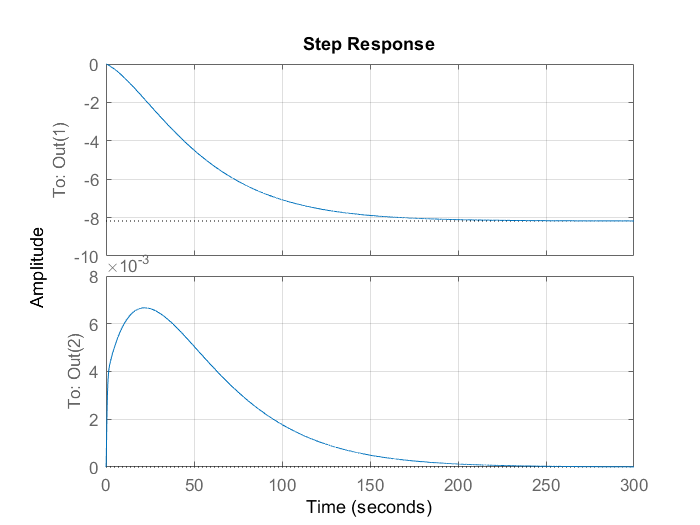

stepplot(ss(A-B1*K1,B1,C,0)); grid on;


[V, D] = eig(A-B1*K1);
sensibilite = cond(V);
disp('Sensitivité en mode dégradé (U_2 inactive) :'); disp(sensibilite);

Sensitivité en mode dégradé (U_2 inactive) :
   4.5121e+03

